%CONTROL PID DIGITAL PARA SISTEMAS SISO

clc;clear all; close all;
syms z s

Ts = 0.1;
Gs = 1/((s+1)*(s+3))

$$Gs = \frac{1}{\left(s+1\right)\,\left(s+3\right)}$$

Gz_EulerBackward = subs(Gs,s,(1-z^-1)/Ts)

$$Gz\_EulerBackward = \frac{1}{\left(\frac{10}{z}-11\right)\,\left(\frac{10}{z}-13\right)}$$

Gz = Sym_tfz(Gz_EulerBackward,Ts)

Gz =
 
      0.006993 z^2
  ---------------------
  (z-0.9091) (z-0.7692)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties




%Error en escalon en Feedback
G1 = evalfr(Gz,1);
ess = 1/( 1 + G1)

ess = 0.7500


Glc = zpk(Gz/(1+Gz))

Glc =
 
  0.0069444 z^2 (z-0.9091) (z-0.7692)
  -----------------------------------
  (z-0.9091) (z-0.8333)^2 (z-0.7692)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


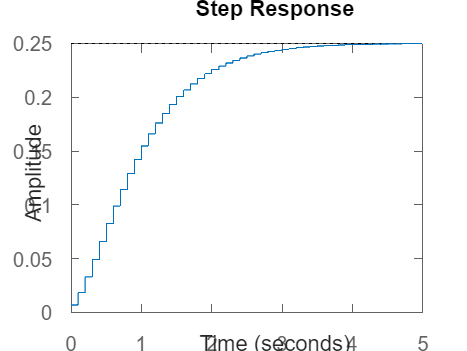

step(Glc)

function Zz = Sym_tfz(Gz,ts)
   [num_z, den_z] = numden(Gz); 
    num_coeff = sym2poly(num_z);
    den_coeff = sym2poly(den_z); 
    z = tf('z', ts); 
    Zz = zpk(tf(num_coeff, den_coeff, ts)); 
end